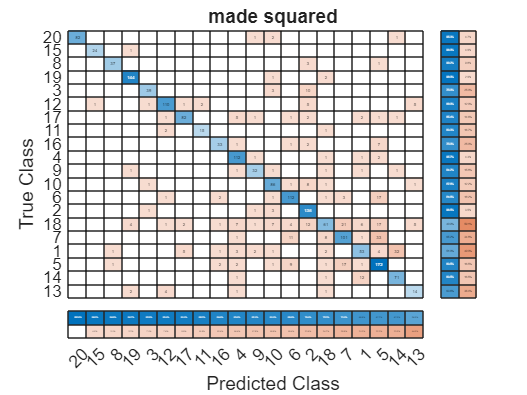

clear all
warning off


%load dataset
datas=44;
load(strcat('Datas_',int2str(datas)),'DATA');
NF= size(DATA{3},1); %number of folds
DIV=DATA{3};%for the division between training and test set
DIM1=DATA{4};%training patterns number
DIM2=DATA{5};%total patterns number
yE=DATA{2};%label of all the patterns
NX=DATA{1};%images

DIM1 = 3016 % 3016<-3771*0.8

%load pre-trained AlexNet
net = alexnet;  %load AlexNet
siz=[227 227];

%parameters
miniBatchSize = 30;
learningRate = 1e-4;
metodoOptim='sgdm';
options = trainingOptions(metodoOptim,...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',30,...
    'InitialLearnRate',learningRate,...
    'Verbose',false,...
    'Plots','training-progress');
numIterationsPerEpoch = floor(DIM1/miniBatchSize);


for fold=1:NF
    close all force
    
    trainPattern=(DIV(fold,1:DIM1));
    testPattern=(DIV(fold,DIM1+1:DIM2));
    y=yE(DIV(fold,1:DIM1));%training label
    yy=yE(DIV(fold,DIM1+1:DIM2));%test label
    numClasses = max(y);%number of classes
    
    %create training set
    clear nome trainingImages
    for pattern=1:DIM1
        IM=NX{DIV(fold,pattern)};%image
         
        %insert here any pre-processing on the IM image    
        USH = imsharpen(IM, "amount", 3, 'radius', 1.5);
        USH = make_square(USH);
        
        USH = imresize(USH,[siz(1) siz(2)]);
        IM = USH;
        
        if size(IM,3) == 1
            IM(:,:,1)=USH;
            IM(:,:,2)=USH;
            IM(:,:,3)=USH;
        end

        %{
        %implementation of 'A Hybrid Convolutional Neural Network for Plankton Classification'
        %Jialun Dai et al.
        GRAY = rgb2gray(IM);
        %GRAY = make_square(GRAY);
        CANNY = edge(GRAY,"canny");
        SOB = imbilatfilt(GRAY);
        SOB = edge(SOB,"sobel");
        
        IM = imresize(IM,[siz(1) siz(2)]);
        SOB = imresize(SOB,[siz(1) siz(2)]);
        GRAY = imresize(GRAY,[siz(1) siz(2)]);
        CANNY = imresize(CANNY,[siz(1) siz(2)]);
        
        IM(:,:,1)=SOB;
        IM(:,:,2)=GRAY;
        IM(:,:,3)=CANNY;
        %}
        
        trainingImages(:,:,:,pattern)= IM;

    end
    imageSize=size(IM);
    
    %data augmentation
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXScale',[1 2]);
    trainingImages = augmentedImageDatastore(imageSize,trainingImages,categorical(y'),'DataAugmentation',imageAugmenter);
    
    %tuning della rete
    % The last three layers of the pretrained network net are configured for 1000 classes.
    %These three layers must be fine-tuned for the new classification problem. Extract all layers, except the last three, from the pretrained network.
    layersTransfer = net.Layers(1:end-3);
    layers = [
        layersTransfer
        fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
        softmaxLayer
        classificationLayer];
    netTransfer = trainNetwork(trainingImages,layers,options);
    
    %test set
    clear nome test testImages
    for pattern=ceil(DIM1)+1:ceil(DIM2)
        IM=NX{DIV(fold,pattern)};%image
        
        %insert here any pre-processing on the IM image
        USH = imsharpen(IM, "amount", 3, 'radius', 1.5);
        USH = make_square(USH);
        
        USH = imresize(USH,[siz(1) siz(2)]);
        IM = USH;
        
        if size(IM,3) == 1
            IM(:,:,1)=USH;
            IM(:,:,2)=USH;
            IM(:,:,3)=USH;
        end

        %{
        %implementation of 'A Hybrid Convolutional Neural Network for Plankton Classification'
        %Jialun Dai et al.
        GRAY = rgb2gray(IM);
        %GRAY = make_square(GRAY);
        CANNY = edge(GRAY,"canny");
        SOB = imbilatfilt(GRAY);
        SOB = edge(SOB,"sobel");
        
        IM = imresize(IM,[siz(1) siz(2)]);
        SOB = imresize(SOB,[siz(1) siz(2)]);
        GRAY = imresize(GRAY,[siz(1) siz(2)]);
        CANNY = imresize(CANNY,[siz(1) siz(2)]);
        
        IM(:,:,1)=SOB;
        IM(:,:,2)=GRAY;
        IM(:,:,3)=CANNY;
        %}
        
        testImages(:,:,:,pattern-ceil(DIM1))=IM;
    end

    %classifying test patterns
    [outclass, score{fold}] =  classify(netTransfer,testImages);
    
    %accuracy
    [a,b]=max(score{fold}');
    ACC(fold)=sum(b==yy)./length(yy);

    %save whatever you need
    outclass = transpose(outclass);
    yy = categorical(yy);
    figure
    cm = confusionchart(yy,outclass);
    cm.Normalization = 'column-normalized';
    sortClasses(cm,'descending-diagonal')
    cm.Normalization = 'absolute';  
    cm.ColumnSummary = 'column-normalized';
    cm.RowSummary = 'row-normalized';
    figName = sprintf("Preprocessing_fold%d_acc_%0.5f.fig",fold,ACC(fold));
    savefig(gcf,figName);
    %%%%%
    
end